クローバをかけた時の電流波形

clearvars -except fitrate1
yourname = 'C:\Users\Moe Akimitsu\';
f = fullfile(yourname,'Documents','GitHub','test-open');
addpath(genpath(f));
%addpath(fullfile(yourname,'Documents','GitHub','test-open','pcb'));
f = fullfile(yourname,'Documents','GitHub','SXR_test');
addpath(f);

%%%適宜変更
%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier='I:';%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得
 node='Crowbar_us_';  % 検索する列の名前. T.Properties.VariableNamesで一覧表示できる
 pat=454;   % 検索パターン（数値なら一致検索、文字なら含む検索）　

subT=searchlog(T,node,pat);% ログのテーブルから当てはまるものを抽出した新しいテーブルを作成
%prompt = 'number: '
%shotlist=[3394,];
%subT=T(shotlist,:);
%IDXlist=shotlist(isfinite(subT.d_tacq));
%IDX=T.number
%IDX=input(prompt)
IDXlist=[[2911:2913] [2924:2926] [2928] [2930] [2933]];% [2942:2943] [2945:2949]

IDXlist =         2911        2912        2913        2924        2925        2926        2928        2930        2933


%IDXlist=2983
start=460;

start = 460

frame=50;

frame = 50

IDX = 2911

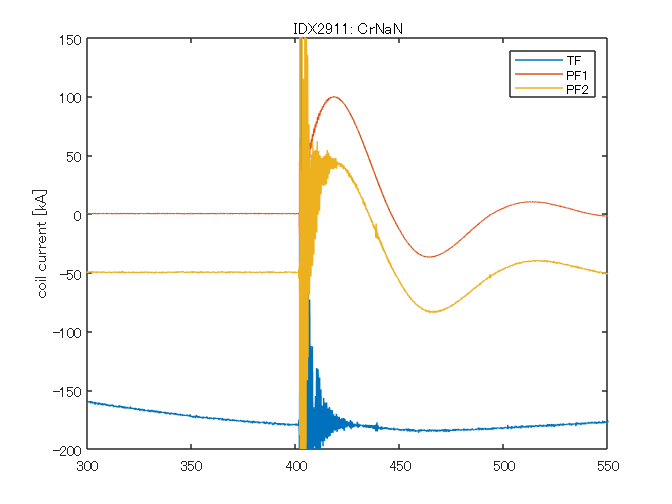

使い方によるエラー fscanf
ファイルの識別子が無効です。有効なファイルの識別子を生成するには fopen を使用してください。

エラー: get_B_z/read_mrd_file (行 161)
    assert(module_count == fscanf(fileID,'%d',1));

エラー: get_B_z (行 46)
data = read_mrd_file(data_dir,ch_per_module,module_count,time_count);

エラー: <a href="ma

for i=1:numel(IDXlist)
IDX=IDXlist(i)
fitrate(:,i) = fitratecalc(T, IDX, pathname,start,frame);
end

figure
%plot(repmat([1:50]+465,9,1)',fitrate)
h=plot(repmat([1:frame]+start,3,1)',[mean(fitrate(:,1:3),2),mean(fitrate(:,4:7),2),mean(fitrate(:,8:9),2)])
hold on
 ar1 = area(([1:frame]+start),[max(fitrate(:,1:3),[],2), min(fitrate(:,1:3),[],2)-max(fitrate(:,1:3),[],2)]);
% Appearances
%set(h,'Color',('r','b','c'))
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor',[0 0.2 1],'FaceAlpha',0.2,'LineStyle','None')
 ar2 = area(([1:frame]+start),[max(fitrate(:,4:7),[],2), min(fitrate(:,4:7),[],2)-max(fitrate(:,4:7),[],2)]);
% Appearances
%set(h,'Color',('r','b','c'))
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor',[1.0,0.2,0.0],'FaceAlpha',0.2,'LineStyle','None')
 ar3 = area(([1:frame]+start),[max(fitrate(:,8:9),[],2), min(fitrate(:,8:9),[],2)-max(fitrate(:,8:9),[],2)]);
% Appearances
%set(h,'Color',('r','b','c'))
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor',[1 0.8 0],'FaceAlpha',0.2,'LineStyle','None')
hold off
grid on

ylabel('合体率')
xlabel('time')
%legend('no Cr','no Cr','no Cr','Cr454us','Cr454us','Cr454us','Cr454us','Cr450us','Cr450us')
legend('no Cr','Cr454us','Cr450us')

function rgwdata = importfile(filename, dataLines)
%IMPORTFILE テキスト ファイルからデータをインポート
%  UNTITLED = IMPORTFILE(FILENAME) は既定の選択に関してテキスト ファイル FILENAME
%  からデータを読み取ります。  データを table として返します。
%
%  UNTITLED = IMPORTFILE(FILE, DATALINES) はテキスト ファイル FILENAME
%  の指定された行区間のデータを読み取ります。DATALINES
%  を正の整数スカラーとして指定するか、行区間が不連続の場合は正の整数スカラーからなる N 行 2 列の配列として指定します。
%
%  例:
%  Untitled = importfile("X:\results\ts-3u\211222\211222006.rgw", [1, Inf]);
%
%  READTABLE も参照してください。
%
% MATLAB からの自動生成日: 2022/01/15 13:57:51

%% 入力の取り扱い

% dataLines が指定されていない場合、既定値を定義します
if nargin < 2
    dataLines = [1, Inf];
end

%% インポート オプションの設定およびデータのインポート
opts = delimitedTextImportOptions("NumVariables", 18);

% 範囲と区切り記号の指定
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% 列名と型の指定
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "ch6", "ch7", "ch8", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"];
opts.SelectedVariableNames = ["ch6", "ch7", "ch8"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 変数プロパティを指定
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"], "EmptyFieldRule", "auto");

% データのインポート
rgwdata = readtable(filename, opts);

end

function fitrate = fitratecalc(T, IDX, pathname,start,frame)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
offset_TF=isfinite(TF_shot);
%start=T.Period_StartTime_(IDX);
if isnan(T.EF_A_(IDX))
    i_EF=150;
else  
    i_EF=T.EF_A_(IDX);
end
filepath.rgw=strcat(pathname.ts3u, '\', string(date),'\' ...
    ,string(date),num2str(shot,'%03i'),'.rgw');

rgwdata = importfile(filepath.rgw);
rgwdata.ch6=rgwdata.ch6*(65.7146)*12;
rgwdata.ch7=rgwdata.ch7*(-57.6030)*3;
rgwdata.ch8=rgwdata.ch8*(-187.170)*3-50;
plot(repmat([0:0.1:0.1*10000],3,1)',rgwdata{2:end,:})
legend('TF','PF1','PF2')
ylabel('coil current [kA]')
ylim([-200 150])
xlim([300 550])
title(strcat('IDX',num2str(IDX),': Cr',num2str(T.Crowbar_us_(IDX))))
hold off


[B_z,r_probe,z_probe,ch_dist,data,data_raw,shot_num]= get_B_z(date,TF_shot,shot,offset_TF,i_EF,pathname.ts3u);
B_z = B_z([2,3,4,6,7,8],2:end,:);
data = data([2,3,4,6,7,8],2:end,:);
z_probe = z_probe(2:end);
ch_dist = ch_dist([2,3,4,6,7,8],2:end);
r_probe = r_probe([2,3,4,6,7,8]);
figure

z_space = linspace(z_probe(1),z_probe(end),50);
r_space = linspace(r_probe(1),r_probe(end),50);
[psi_mesh_z,psi_mesh_r] = meshgrid(z_space,r_space);
for i=1:frame
    psi  = get_psi(B_z,r_probe,i+start);
    psi_store(:,:,i)= griddata(z_probe,r_probe,psi,psi_mesh_z,psi_mesh_r,'cubic');
end

[max_psi,max_psi_r]=max(psi_store,[],1);
max_psi=squeeze(max_psi);
%plot(max_psi)
for i=1:frame
    max_psi_ind=find(islocalmax(smooth(max_psi(:,i)),'MaxNumExtrema', 2));
    if numel(max_psi(min(max_psi_ind),i))==0
    psi_pr(1,i)=NaN;
    else
    psi_pr(1,i)=max_psi(min(max_psi_ind),i);
    end
    if numel(max_psi(max(max_psi_ind),i))==0
    psi_pr(2,i)=NaN;
    else
    psi_pr(2,i)=max_psi(max(max_psi_ind),i);
    end
    if numel(find(islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1)))==0
        psi_pr(3,i)=NaN;
    else
        min_psi_ind=islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1);
        psi_pr(3,i)=max_psi(min_psi_ind,i);
    end
    if max_psi(1,i)==max(max_psi(1:end/2,i))
        psi_pr(1,i)=max_psi(1,i);
    end    
    if max_psi(end,i)==max(max_psi(end/2:end,i))
        psi_pr(2,i)=max_psi(end,i);
    end
end
figure('Position',[700,350,350,300])
plot(repmat([1:frame]+start,3,1)',psi_pr','--o')
ylabel('psi[Wb]')
xlabel('time')
legend('Psi_{private1}','psi_{private2}','Psi_{common}')
fitrate=psi_pr(3,:)./min(psi_pr(1:2,:),[],1);
end